lin_1(1)

ans = -0.0030

lin_2(1)

ans = -0.0021

lin_3(1)

ans = -0.0013

lin_4(1)

ans = -7.8348e-04

lin_5(1)

ans = -4.6755e-04


k = [lin_1(1), lin_2(1), lin_3(1), lin_4(1), lin_5(1)];

[size_1, n_1] = size(time_1);
[size_2, n_2] = size(time_2);
[size_3, n_3] = size(time_3);
[size_4, n_4] = size(time_4);
[size_5, n_5] = size(time_5);

DV_1 = mean((lnV_1 - mean(lnV_1)).^2);
Dt_1 = mean((time_1 - mean(time_1)).^2);
DV_2 = mean((lnV_2 - mean(lnV_2)).^2);
Dt_2 = mean((time_2 - mean(time_2)).^2);
DV_3 = mean((lnV_3 - mean(lnV_3)).^2);
Dt_3 = mean((time_3 - mean(time_3)).^2);
DV_4 = mean((lnV_4 - mean(lnV_4)).^2);
Dt_4 = mean((time_4 - mean(time_4)).^2);
DV_5 = mean((lnV_5 - mean(lnV_5)).^2);
Dt_5 = mean((time_5 - mean(time_5)).^2);

% sigma k
sigma_1 = sqrt(1/size_1 * (DV_1 / Dt_1 - lin_1(1)^2))

sigma_1 = 1.2171e-05

sigma_2 = sqrt(1/size_2 * (DV_2 / Dt_2 - lin_2(1)^2))

sigma_2 = 6.0965e-06

sigma_3 = sqrt(1/size_3 * (DV_3 / Dt_3 - lin_3(1)^2))

sigma_3 = 4.4507e-06

sigma_4 = sqrt(1/size_4 * (DV_4 / Dt_4 - lin_4(1)^2))

sigma_4 = 3.0534e-06

sigma_5 = sqrt(1/size_5 * (DV_5 / Dt_5 - lin_5(1)^2))

sigma_5 = 1.2506e-06


sigma_k = [sigma_1, sigma_2, sigma_3, sigma_4, sigma_5];

V = 600; % см^3
mu = 5.5; % см^(-1)

s = [1/40, 1/60, 1/90, 1/140, 1/250];

D_1 = -V * mu *lin_1(1)

D_1 = 9.7443

D_2 = -V * mu *lin_2(1)

D_2 = 7.0261

D_3 = -V * mu *lin_3(1)

D_3 = 4.4212

D_4 = -V * mu *lin_4(1)

D_4 = 2.5855

D_5 = -V * mu *lin_5(1)

D_5 = 1.5429


D = [D_1, D_2, D_3, D_4, D_5];
eps_V = 15/600;
eps_mu = 0.5/5.5;
eps_k = sigma_k./k;

err = zeros(5, 1);

for i = 1 : 5
    err(i) = D(i) * sqrt(eps_V^2 + eps_k(i)^2 + eps_mu^2);
end
% sigma D
err

err =     0.9196
    0.6628
    0.4171
    0.2440
    0.1455


% коэффициенты полинома
p = polyfit(s, D, 1)

p =   401.2463   -0.0656



% сгенерируем точки, равномерно расположенные на области определения данных
xx = linspace(s(1), s(end), 100);

% получим значения полиномов в этих точках
yy = polyval(p, xx);

p(1)/760

ans = 0.5280

fig = figure

fig =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


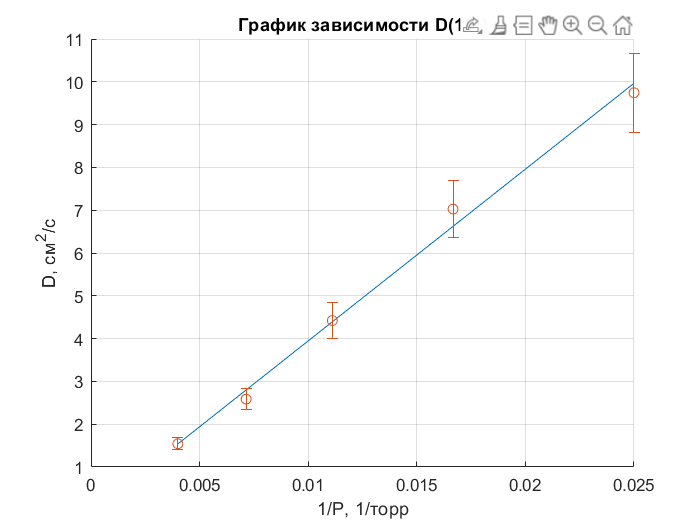


hold on

plot(xx, yy);
errorbar(s, D, err, 'o');

xlabel('1/P, 1/торр');
ylabel('D, см^2/c');
title('График зависимости D(1/P)');
grid on
hold off

set(fig, 'Visible', 'on')

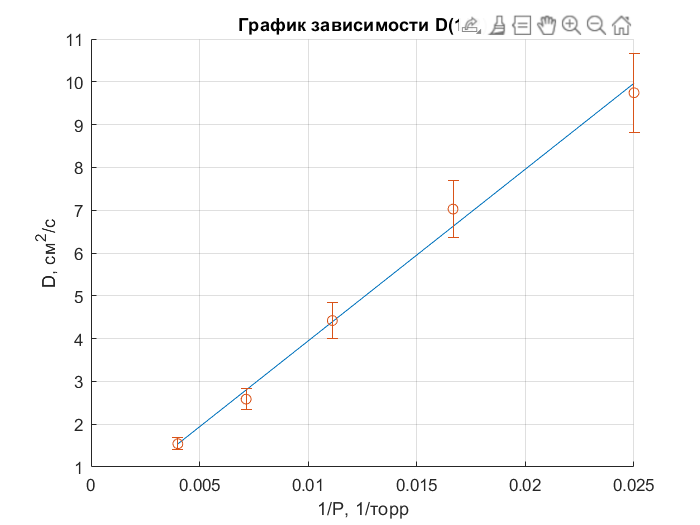

%saveas(fig, "version_0.png");